# Example - DC Stark

clear all
addpath("Molecules\");addpath("Atoms\")
C = Constants;
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesBox','on')
set(groot,'defaultAxesLineWidth',0.5)

## Define Fields

maxN = 2;
B.value = [200];
B.dir = [0,0,1];
B.scaling = 1e-4; %put B.value in Gauss, not Tesla
E.value = linspace(0,200,51); %V/m
E.dir = [0,0,1];
E.scaling = 1e2;%put E.value in V/cm, not V/m
I.value = [0];
I.dir = [0,0,1];
I.pol = [0,1,0];
I.scaling = 1e7;%put I.value in mW/cm^2, not W/m^2
Fields.B = B;
Fields.E = E;
Fields.I = I;

## Define Hamiltonian

Mol = RbCs(87,133);
Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
H0 = Ham.hyperfine.total + I.value*I.scaling*Ham.ac_stark + B.value*B.scaling*Ham.zeeman;
Base = Ham.Basis;
nStates = Base.NStates;

## Diagonalise for varying intensity

F = E;
x = F.value;
energyMap = nan(length(x),nStates);
statesMap = nan(length(x),nStates,nStates);
for k = 1:length(x)
    if mod(k,10)==1; fprintf("%d - ",k); end
    H = H0 + x(k)*F.scaling*Ham.dc_stark;
    [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
    [d,sortIdx] = sort(real(D));
    energyMap(k,:)=d;        
    statesMap(k,:,:) = V(:,sortIdx);
end

1 - 11 - 21 - 31 - 41 - 51 - 

disp("Finished")

Finished


## Plot Results

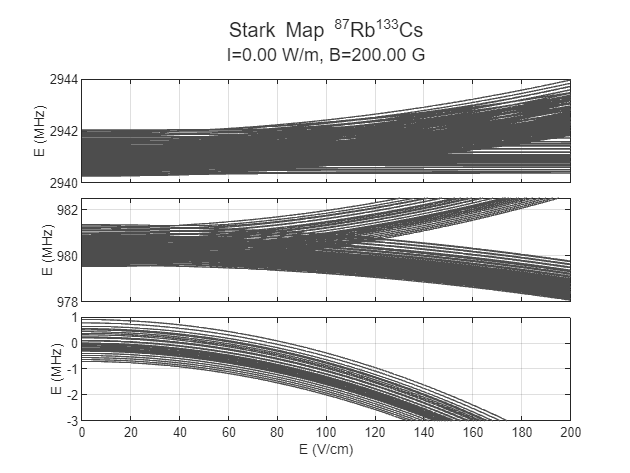

N = Base.getStates("N");
figure(11); clf;
t = tiledlayout(3,1, "TileSpacing","tight");
nexttile(t,3); %N=0 manifold
plot(x,energyMap(:,N==0)*1e-6, color=[1,1,1]*0.3); hold on;
xlabel("E (V/cm)")
ylabel(sprintf("E (MHz)"))
ylim([-3,1])
xlim([min(x),max(x)])
% axis square

nexttile(t,2); %N=1 manifold
plot(x,energyMap(:,N==1)*1e-6, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
xticklabels([])
ylim([978,982.5])
xlim([min(x),max(x)])
% axis square

nexttile(t,1); %N=1 manifold
plot(x,energyMap(:,N==2)*1e-6, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
xticklabels([])
% ylim([1,4]+5880)
xlim([min(x),max(x)])
% axis square

title(t,sprintf("Stark Map %s",Mol.name))
subtitle(t, sprintf("I=%.2f W/m, B=%.2f G", Fields.I.value,Fields.B.value))

Subtract mean energy (useful when going to very large fields where more state-mixing happens)

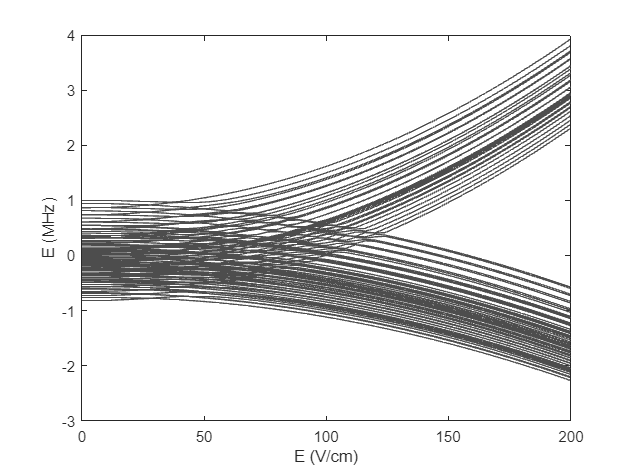

en = energyMap(:,N==1);
figure(14); clf;
plot(x,(en-mean(en,2))*1e-6, color=[1,1,1]*0.3); hold on;
xlabel("E (V/cm)")
ylabel(sprintf("E (MHz)"))
% ylim([-1.5,1])
xlim([min(x),max(x)])
grid off

## Induced Dipole Moment